data = ulogreader("log_11_2023-3-22-17-19-42.ulg")

data =   ulogreader with properties:

            FileName: "log_11_2023-3-22-17-19-42.ulg"
           StartTime: 00:01:02.714798
             EndTime: 00:09:09.029858
     AvailableTopics: [6×5 table]
    DropoutIntervals: [0×2 duration]


%extract actuator data
actuator_data = data.readTopicMsgs('TopicNames',"actuator_controls_0",'InstanceID',{0});
actuator = actuator_data.TopicMessages{1};
% uint64 timestamp			# time since system start (microseconds)
% uint8 NUM_ACTUATOR_CONTROLS = 8
% uint8 NUM_ACTUATOR_CONTROL_GROUPS = 6
% uint8 INDEX_ROLL = 0
% uint8 INDEX_PITCH = 1
% uint8 INDEX_YAW = 2
% uint8 INDEX_THROTTLE = 3
% uint8 INDEX_FLAPS = 4
% uint8 INDEX_SPOILERS = 5
% uint8 INDEX_AIRBRAKES = 6
% uint8 INDEX_LANDING_GEAR = 7
% uint8 INDEX_GIMBAL_SHUTTER = 3
% uint8 INDEX_CAMERA_ZOOM = 4
% 
% uint64 timestamp_sample	    # the timestamp the data this control response is based on was sampled
% float32[8] control
control1 = timetable(actuator.timestamp,actuator.control(:,1),'VariableNames',{'Control1'}); 
control2 = timetable(actuator.timestamp,actuator.control(:,2),'VariableNames',{'Control2'}); 
control3 = timetable(actuator.timestamp,actuator.control(:,3),'VariableNames',{'Control3'}); 
control4 = timetable(actuator.timestamp,actuator.control(:,4),'VariableNames',{'Control4'}); 
control5 = timetable(actuator.timestamp,actuator.control(:,5),'VariableNames',{'Control5'}); 
control6 = timetable(actuator.timestamp,actuator.control(:,6),'VariableNames',{'Control6'}); 
control7 = timetable(actuator.timestamp,actuator.control(:,7),'VariableNames',{'Control7'}); 
control8 = timetable(actuator.timestamp,actuator.control(:,8),'VariableNames',{'Control8'}); 

%extract sensor data
sensor_data = data.readTopicMsgs('TopicNames',"sensor_combined",'InstanceID',{0});
sensor = sensor_data.TopicMessages{1};
% uint64 timestamp				# time since system start (microseconds)
% 
% int32 RELATIVE_TIMESTAMP_INVALID = 2147483647	# (0x7fffffff) If one of the relative timestamps is set to this value, it means the associated sensor values are invalid
% 
% # gyro timstamp is equal to the timestamp of the message
% float32[3] gyro_rad			# average angular rate measured in the FRD body frame XYZ-axis in rad/s over the last gyro sampling period
% uint32 gyro_integral_dt		# gyro measurement sampling period in microseconds
% 
% int32 accelerometer_timestamp_relative	# timestamp + accelerometer_timestamp_relative = Accelerometer timestamp
% float32[3] accelerometer_m_s2		# average value acceleration measured in the FRD body frame XYZ-axis in m/s^2 over the last accelerometer sampling period
% uint32 accelerometer_integral_dt	# accelerometer measurement sampling period in microseconds

GyroX = timetable(sensor.timestamp,sensor.gyro_rad(:,1),'VariableNames',{'GryoX'}); 
GyroY = timetable(sensor.timestamp,sensor.gyro_rad(:,2),'VariableNames',{'GyroY'}); 
GyroZ = timetable(sensor.timestamp,sensor.gyro_rad(:,3),'VariableNames',{'GyroZ'}); 
AccelX = timetable(sensor.timestamp,sensor.accelerometer_m_s2(:,1),'VariableNames',{'AccelX'}); 
AccelY = timetable(sensor.timestamp,sensor.accelerometer_m_s2(:,2),'VariableNames',{'AccelY'}); 
AccelZ = timetable(sensor.timestamp,sensor.accelerometer_m_s2(:,3),'VariableNames',{'AccelZ'}); 


%extract angular acceleration
angular_acc_data = data.readTopicMsgs('TopicNames',"vehicle_angular_acceleration",'InstanceID',{0});
angular_acc = angular_acc_data.TopicMessages{1};
% uint64 timestamp        # time since system start (microseconds)
% uint64 timestamp_sample # timestamp of the data sample on which this message is based (microseconds)
%
% float32[3] xyz          # angular acceleration about the FRD body frame XYZ-axis in rad/s^2
p=timetable(angular_acc.timestamp,angular_acc.xyz(:,1), 'VariableNames',{'p'}); 
q=timetable(angular_acc.timestamp,angular_acc.xyz(:,2), 'VariableNames',{'q'});     
r=timetable(angular_acc.timestamp,angular_acc.xyz(:,3), 'VariableNames',{'r'}); 

%extract global position
position_data = data.readTopicMsgs('TopicNames',"vehicle_global_position",'InstanceID',{0});
position = position_data.TopicMessages{1};
% # Fused global position in WGS84.
% # This struct contains global position estimation. It is not the raw GPS
% # measurement (@see vehicle_gps_position). This topic is usually published by the position
% # estimator, which will take more sources of information into account than just GPS,
% # e.g. control inputs of the vehicle in a Kalman-filter implementation.
% #
% 
% uint64 timestamp		# time since system start (microseconds)
% uint64 timestamp_sample         # the timestamp of the raw data (microseconds)
% 
% float64 lat			# Latitude, (degrees)
% float64 lon			# Longitude, (degrees)
% float32 alt			# Altitude AMSL, (meters)
% float32 alt_ellipsoid		# Altitude above ellipsoid, (meters)

lat=timetable(position.timestamp,position.lat, 'VariableNames',{'lat'});
lon=timetable(position.timestamp,position.lon, 'VariableNames',{'lon'});
alt=timetable(position.timestamp,position.alt, 'VariableNames',{'alt'});
sp=timetable(position.timestamp,position.alt*0, 'VariableNames',{'sp'});
an=timetable(position.timestamp,position.alt*0, 'VariableNames',{'an'});
sat=timetable(position.timestamp,position.alt*0, 'VariableNames',{'sat'});


customPlotter = flightLogSignalMapping;
customData.Gyro = [GyroX GyroY GyroZ];
customData.Accel = [AccelX AccelY AccelZ];
customData.control  = [control1 control2 control3 control4 control5 control6 control7 control8];
customData.Angular_acc = [p q r];
customData.position = [lat lon alt sp an sat];

timeAccess = @(x)x.Gyro.Time;
gyroAccess = @(x)x.Gyro(:,1:3);
mapSignal(customPlotter,"Gyro",timeAccess,gyroAccess);
timeAccess = @(x)x.Accel.Time;
accelAccess = @(x)x.Accel(:,1:3);
mapSignal(customPlotter, "Accel", timeAccess, accelAccess);
timeAccess = @(x)x.Angular_acc.Time;
accelAccess2 = @(x)x.Angular_acc(:,1:3);
mapSignal(customPlotter, "Accel2", timeAccess, accelAccess2);
timeAccess = @(x)x.position.Time;
GPSAccess = @(x)x.position(:,1:6);
mapSignal(customPlotter, "GPS", timeAccess, GPSAccess);
checkSignal(customPlotter,customData);

--------------------------------------------
SignalName: Gyro
Pass
--------------------------------------------
SignalName: Accel
Pass
--------------------------------------------
SignalName: Accel2
Pass
--------------------------------------------
SignalName: GPS
Pass


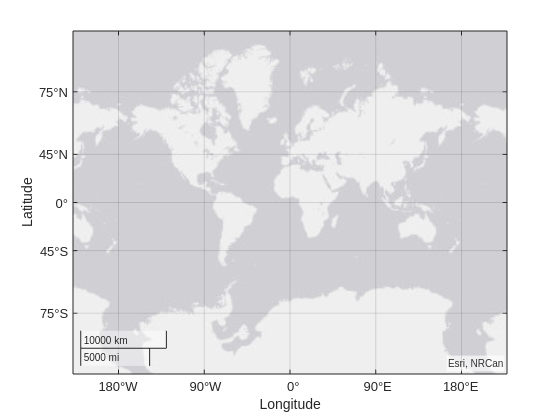

Error using geoplot
Invalid subscript for lat. A table variable subscript must be a numeric array containing real positive integers, a logical array, a character vector, a string array, a cell array
of character vectors, or a pattern scalar used to match variable names.

Error in uav.internal.log.plotter.mav.plotGPS2D (line 19)
    geoplot(ax, lat, lon, 'LineWidth', 2);

Error in 

stackedplot(msgs.Messages{1},{'roll','pitch','yaw'});
show(customPlotter,customData);